clear all
syms b1 b2 b3 q1 q2 q3 dq1 dq2 dq3 ddq1 ddq2 ddq3 L1 L2 L3 Lc1 Lc2 Lc3 m1 m2 m3 I1 I2 I3 h g real



T00 = eye(4);
T01 = Rz(q1)*Tz(L1);
T02 = Rz(q1)*Tz(L1) * Rx(q2)* Tx(L2)

$$T02 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & L_{2}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & L_{2}\,\sin\left(q_{1}\right)\\ 0 & \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T03 = Rz(q1)*Tz(L1) * Rx(q2)* Tx(L2) * Tz(q3)

$$T03 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & L_{2}\,\cos\left(q_{1}\right)+q_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & L_{2}\,\sin\left(q_{1}\right)-q_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 0 & \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & L_{1}+q_{3}\,\cos\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$


R1 = T01(1:3,1:3)

$$R1 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R2 = T02(1:3,1:3)

$$R2 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 0 & \sin\left(q_{2}\right) & \cos\left(q_{2}\right) \end{array}\right)$$

R3 = T03(1:3,1:3)

$$R3 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 0 & \sin\left(q_{2}\right) & \cos\left(q_{2}\right) \end{array}\right)$$


Lc1 = L1/2

$$Lc1 = \frac{L_{1}}{2}$$

Lc2 = L2/2

$$Lc2 = \frac{L_{2}}{2}$$


T01C = Rz(q1)*Tz(Lc1);
T02C = Rz(q1)*Tz(L1) * Rx(q2)* Tx(Lc2)

$$T02C = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & \frac{L_{2}\,\cos\left(q_{1}\right)}{2}\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & \frac{L_{2}\,\sin\left(q_{1}\right)}{2}\\ 0 & \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T03C = Rz(q1)*Tz(L1) * Rx(q2)* Tx(L2) * Tz(q3 - L3/2)

$$T03C = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & L_{2}\,\cos\left(q_{1}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(\frac{L_{3}}{2}-q_{3}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & L_{2}\,\sin\left(q_{1}\right)+\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(\frac{L_{3}}{2}-q_{3}\right)\\ 0 & \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & L_{1}-\cos\left(q_{2}\right)\,\left(\frac{L_{3}}{2}-q_{3}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$


O0 = T00(1:3,4)

O0 =      0
     0
     0


O1 = T01(1:3,4)

$$O1 = \left(\begin{array}{c} 0\\ 0\\ L_{1} \end{array}\right)$$

O2 = T02(1:3,4)

$$O2 = \left(\begin{array}{c} L_{2}\,\cos\left(q_{1}\right)\\ L_{2}\,\sin\left(q_{1}\right)\\ L_{1} \end{array}\right)$$

O3 = T03(1:3,4)

$$O3 = \left(\begin{array}{c} L_{2}\,\cos\left(q_{1}\right)+q_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ L_{2}\,\sin\left(q_{1}\right)-q_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ L_{1}+q_{3}\,\cos\left(q_{2}\right) \end{array}\right)$$

O1c = T01C(1:3,4)

$$O1c = \left(\begin{array}{c} 0\\ 0\\ \frac{L_{1}}{2} \end{array}\right)$$

O2c = T02C(1:3,4)

$$O2c = \left(\begin{array}{c} \frac{L_{2}\,\cos\left(q_{1}\right)}{2}\\ \frac{L_{2}\,\sin\left(q_{1}\right)}{2}\\ L_{1} \end{array}\right)$$

O3c = T03C(1:3,4)

$$O3c = \left(\begin{array}{c} L_{2}\,\cos\left(q_{1}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(\frac{L_{3}}{2}-q_{3}\right)\\ L_{2}\,\sin\left(q_{1}\right)+\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(\frac{L_{3}}{2}-q_{3}\right)\\ L_{1}-\cos\left(q_{2}\right)\,\left(\frac{L_{3}}{2}-q_{3}\right) \end{array}\right)$$


z0 = T00(1:3,3) %Rz

z0 =      0
     0
     1


z1 = T01(1:3,1) %Rx

$$z1 = \left(\begin{array}{c} \cos\left(q_{1}\right)\\ \sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

z2 = T02(1:3,3) %Tz

$$z2 = \left(\begin{array}{c} \sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \cos\left(q_{2}\right) \end{array}\right)$$

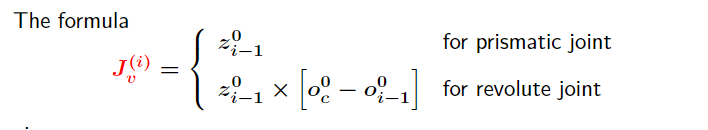

zero = [0;0;0];
Jv1 = [cross(z0,(O1c - O0)), zero, zero]

$$Jv1 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

Jv2 = [cross(z0,(O2c - O0)), cross(z1,(O2c - O1)),zero]

$$Jv2 = \left(\begin{array}{ccc} -\frac{L_{2}\,\sin\left(q_{1}\right)}{2} & 0 & 0\\ \frac{L_{2}\,\cos\left(q_{1}\right)}{2} & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

Jv3 = [cross(z0,(O3c - O0)), cross(z1,(O3c - O1)),z2]

$$Jv3 = \begin{array}{l} \left(\begin{array}{ccc} -L_{2}\,\sin\left(q_{1}\right)-\sigma_{2} & -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\left(\frac{L_{3}}{2}-q_{3}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{1} & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\left(\frac{L_{3}}{2}-q_{3}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 0 & \cos\left(q_{1}\right)\,\left(L_{2}\,\sin\left(q_{1}\right)+\sigma_{2}\right)-\sin\left(q_{1}\right)\,\sigma_{1} & \cos\left(q_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{2}\,\cos\left(q_{1}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(\frac{L_{3}}{2}-q_{3}\right)\\ \sigma_{2}=\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(\frac{L_{3}}{2}-q_{3}\right) \end{array}$$

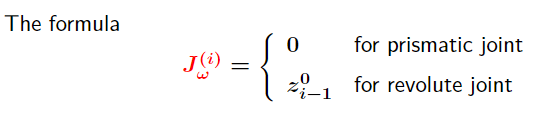

% 4- Jw for joints
% Jw1
Jw1 = [z0, zero,zero]

Jw1 =      0     0     0
     0     0     0
     1     0     0


% Jw2
Jw2 = [z0 ,z1, zero]

$$Jw2 = \left(\begin{array}{ccc} 0 & \cos\left(q_{1}\right) & 0\\ 0 & \sin\left(q_{1}\right) & 0\\ 1 & 0 & 0 \end{array}\right)$$

% Jw3
Jw3 = [z0 ,z1, zero]

$$Jw3 = \left(\begin{array}{ccc} 0 & \cos\left(q_{1}\right) & 0\\ 0 & \sin\left(q_{1}\right) & 0\\ 1 & 0 & 0 \end{array}\right)$$

q = [q1;q2;q3];
D1 = (m1*Jv1')*Jv1 + Jw1'*R1*I1*R1'*Jw1

$$D1 = \left(\begin{array}{ccc} I_{1} & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

D2 = (m2*Jv2')*Jv2 + Jw2'*R2*I2*R2'*Jw2

$$D2 = \begin{array}{l} \left(\begin{array}{ccc} \frac{m_{2}\,{L_{2}}^{2}\,{\cos\left(q_{1}\right)}^{2}}{4}+\frac{m_{2}\,{L_{2}}^{2}\,{\sin\left(q_{1}\right)}^{2}}{4}+I_{2}\,{\cos\left(q_{2}\right)}^{2}+I_{2}\,{\sin\left(q_{2}\right)}^{2} & 0 & 0\\ 0 & I_{2}\,{\cos\left(q_{1}\right)}^{2}\,\sigma_{1}+I_{2}\,{\sin\left(q_{1}\right)}^{2}\,\sigma_{1} & 0\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\cos\left(q_{1}\right)}^{2}+{\sin\left(q_{1}\right)}^{2} \end{array}$$

D3 = (m3*Jv3')*Jv3 + Jw3'*R3*I3*R3'*Jw3

$$D3 = \begin{array}{l} \left(\begin{array}{ccc} m_{3}\,{\sigma_{8}}^{2}+m_{3}\,{\sigma_{7}}^{2}+I_{3}\,{\cos\left(q_{2}\right)}^{2}+I_{3}\,{\sin\left(q_{2}\right)}^{2} & \sigma_{4} & \sigma_{5}\\ \sigma_{4} & m_{3}\,{\sigma_{6}}^{2}+I_{3}\,{\cos\left(q_{1}\right)}^{2}\,\sigma_{1}+I_{3}\,{\sin\left(q_{1}\right)}^{2}\,\sigma_{1}+m_{3}\,{\cos\left(q_{1}\right)}^{2}\,{\cos\left(q_{2}\right)}^{2}\,\sigma_{2}+m_{3}\,{\cos\left(q_{2}\right)}^{2}\,{\sin\left(q_{1}\right)}^{2}\,\sigma_{2} & \sigma_{3}\\ \sigma_{5} & \sigma_{3} & m_{3}\,{\cos\left(q_{1}\right)}^{2}\,{\sin\left(q_{2}\right)}^{2}+m_{3}\,{\cos\left(q_{2}\right)}^{2}+m_{3}\,{\sin\left(q_{1}\right)}^{2}\,{\sin\left(q_{2}\right)}^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\cos\left(q_{1}\right)}^{2}+{\sin\left(q_{1}\right)}^{2}\\ \sigma_{2}={\left(\frac{L_{3}}{2}-q_{3}\right)}^{2}\\ \sigma_{3}=m_{3}\,\cos\left(q_{2}\right)\,\sigma_{6}-m_{3}\,{\cos\left(q_{1}\right)}^{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{2}\right)\,\left(\frac{L_{3}}{2}-q_{3}\right)-m_{3}\,\cos\left(q_{2}\right)\,{\sin\left(q_{1}\right)}^{2}\,\sin\left(q_{2}\right)\,\left(\frac{L_{3}}{2}-q_{3}\right)\\ \sigma_{4}=m_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\left(\frac{L_{3}}{2}-q_{3}\right)\,\sigma_{7}+m_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\left(\frac{L_{3}}{2}-q_{3}\right)\,\sigma_{8}\\ \sigma_{5}=-m_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sigma_{7}-m_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sigma_{8}\\ \sigma_{6}=\cos\left(q_{1}\right)\,\sigma_{8}-\sin\left(q_{1}\right)\,\sigma_{7}\\ \sigma_{7}=L_{2}\,\cos\left(q_{1}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(\frac{L_{3}}{2}-q_{3}\right)\\ \sigma_{8}=L_{2}\,\sin\left(q_{1}\right)+\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(\frac{L_{3}}{2}-q_{3}\right) \end{array}$$

D=D1+D2 + D3;
D=simplify(D)

$$D = \begin{array}{l} \left(\begin{array}{ccc} I_{1}+I_{2}+I_{3}+\frac{{L_{2}}^{2}\,m_{2}}{4}+{L_{2}}^{2}\,m_{3}+\frac{{L_{3}}^{2}\,m_{3}}{8}+\frac{m_{3}\,{q_{3}}^{2}}{2}-\frac{L_{3}\,m_{3}\,q_{3}}{2}-\frac{{L_{3}}^{2}\,m_{3}\,\cos\left(2\,q_{2}\right)}{8}-\frac{m_{3}\,{q_{3}}^{2}\,\cos\left(2\,q_{2}\right)}{2}+\frac{L_{3}\,m_{3}\,q_{3}\,\cos\left(2\,q_{2}\right)}{2} & \sigma_{1} & \sigma_{2}\\ \sigma_{1} & \frac{m_{3}\,{L_{3}}^{2}}{4}-m_{3}\,L_{3}\,q_{3}+m_{3}\,{q_{3}}^{2}+I_{2}+I_{3} & 0\\ \sigma_{2} & 0 & m_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{L_{2}\,m_{3}\,\cos\left(q_{2}\right)\,\left(L_{3}-2\,q_{3}\right)}{2}\\ \sigma_{2}=-L_{2}\,m_{3}\,\sin\left(q_{2}\right) \end{array}$$

P1 =m1*g*T01C(3,4);
P2 = m2*g*T02C(3,4);
P3 = m3*g*T03C(3,4)

$$P3 = g\,m_{3}\,\left(L_{1}-\cos\left(q_{2}\right)\,\left(\frac{L_{3}}{2}-q_{3}\right)\right)$$


P = P1+ P2 +P3;
G1 = diff(P, q1)

$$G1 = 0$$

G2 = diff(P, q2)

$$G2 = g\,m_{3}\,\sin\left(q_{2}\right)\,\left(\frac{L_{3}}{2}-q_{3}\right)$$

G3 = diff(P, q3)

$$G3 = g\,m_{3}\,\cos\left(q_{2}\right)$$


G = [G1; G2; G3]

$$G = \left(\begin{array}{c} 0\\ g\,m_{3}\,\sin\left(q_{2}\right)\,\left(\frac{L_{3}}{2}-q_{3}\right)\\ g\,m_{3}\,\cos\left(q_{2}\right) \end{array}\right)$$

dq = [dq1; dq2; dq3];
ddq = [ddq1; ddq2; ddq3];
C = Coriolis(D,q,dq,3);
C=simplify(C)

$$C = \begin{array}{l} \left(\begin{array}{ccc} -\frac{m_{3}\,\left(L_{3}-2\,q_{3}\right)\,\left(2\,{\mathrm{dq}}_{3}-2\,{\mathrm{dq}}_{3}\,\cos\left(2\,q_{2}\right)-L_{3}\,{\mathrm{dq}}_{2}\,\sin\left(2\,q_{2}\right)+2\,{\mathrm{dq}}_{2}\,q_{3}\,\sin\left(2\,q_{2}\right)\right)}{8} & {\mathrm{dq}}_{1}\,\left(\frac{m_{3}\,\sin\left(2\,q_{2}\right)\,{L_{3}}^{2}}{8}-\frac{m_{3}\,\sin\left(2\,q_{2}\right)\,L_{3}\,q_{3}}{2}+\frac{m_{3}\,\sin\left(2\,q_{2}\right)\,{q_{3}}^{2}}{2}\right)-L_{2}\,{\mathrm{dq}}_{3}\,m_{3}\,\cos\left(q_{2}\right)-\frac{L_{2}\,{\mathrm{dq}}_{2}\,m_{3}\,\sin\left(q_{2}\right)\,\left(L_{3}-2\,q_{3}\right)}{2} & -\frac{m_{3}\,\left(L_{3}\,{\mathrm{dq}}_{1}-2\,{\mathrm{dq}}_{1}\,q_{3}-L_{3}\,{\mathrm{dq}}_{1}\,{\cos\left(q_{2}\right)}^{2}+2\,{\mathrm{dq}}_{1}\,q_{3}\,{\cos\left(q_{2}\right)}^{2}+2\,L_{2}\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}\right)\right)}{2}\\ -\frac{{\mathrm{dq}}_{1}\,m_{3}\,\sin\left(2\,q_{2}\right)\,{\left(L_{3}-2\,q_{3}\right)}^{2}}{8} & -\frac{{\mathrm{dq}}_{3}\,m_{3}\,\left(L_{3}-2\,q_{3}\right)}{2} & -\sigma_{1}\\ -\frac{{\mathrm{dq}}_{1}\,m_{3}\,\left(L_{3}-2\,q_{3}\right)\,\left(\cos\left(2\,q_{2}\right)-1\right)}{4} & \sigma_{1} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\mathrm{dq}}_{2}\,m_{3}\,\left(L_{3}-2\,q_{3}\right)}{2} \end{array}$$